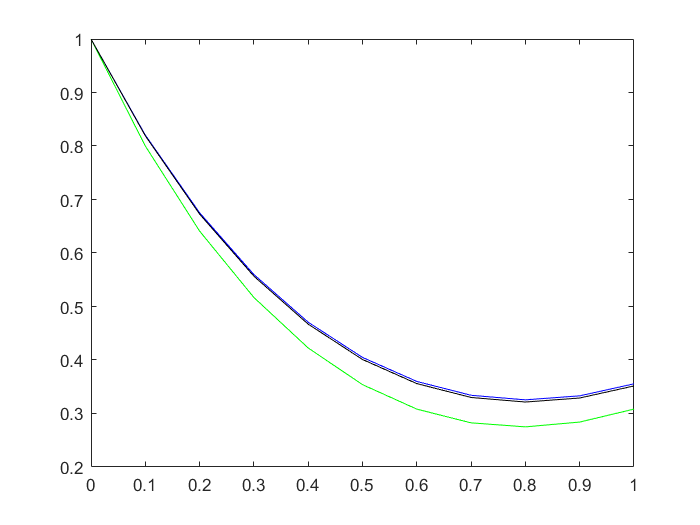

clear
clc
close all
u0=1;
h=0.1;
a=0;
b=1;
n=(b-a)/h;
N=n+1;
x=a:h:b;

u = exact(x, N);
u_1 = runge_kutta_1(u0, x, h, N);
u_2 = runge_kutta_2(u0, x, h, N);
u_4 = runge_kutta_4(u0, x, h, N);
plot(x, u, 'r', x, u_1, 'g',x, u_2, 'b', x, u_4, 'k')

function [u] = exact(x, n)
    u = zeros(1, n);
    for i=1:n
        u(i) = 3/4 * exp(-2 * x(i)) + 1/2*x(i)*x(i)-1/2*x(i)+1/4;
    end
end

function [y] = runge_kutta_1(u_0, x, h, n)
    y = zeros(1, n);
    y(1) = u_0;
    for i = 1:n - 1
        k1 = h * func(y(i), x(i));
        y(i + 1) = y(i) + k1;
    end
end

function [y] = runge_kutta_2(u_0, x, h, n)

y = zeros(1, n);
y(1) = u_0;
    for i = 1:n - 1
        k1 = func(y(i), x(i));
        k2 = func(y(i)+h*k1, x(i)+h);
        y(i + 1) = y(i) + h*(0.5*k1+0.5*k2);
    end
end

function [y] = runge_kutta_4(u_0, x, h, n)
    y = zeros(1, n);
    y(1) = u_0;
    for i = 1:n - 1
        k1 = func(y(i), x(i));
        k2 = func(y(i)+0.5*h*k1, x(i)+0.5*h);
        k3 = func(y(i)+0.5*h*k2, x(i)+0.5*h);
        k4 = func(y(i)+h*k3, x(i)+h);
        y(i + 1) = y(i)+h/6*(k1+2*k2+2*k3+k4);
    end
end